## Refresh

clc;
clear;
close all;
warning('off', 'all')
format long g;
addpath(genpath('GDSAO_uav'));    

## Initialize

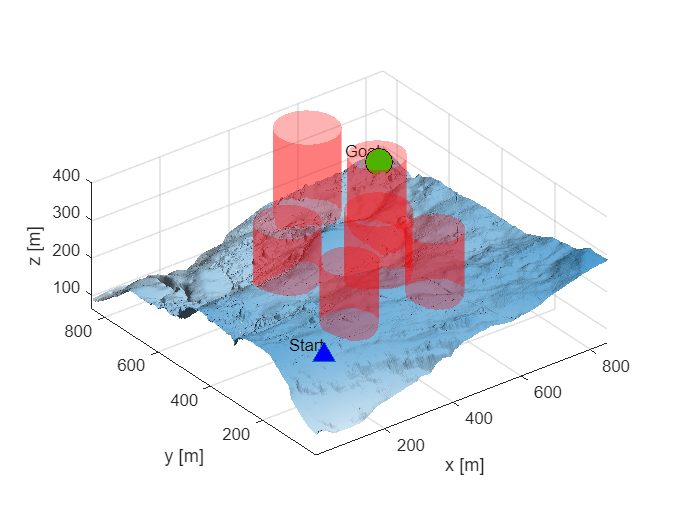

model = CreateModel();  

CostFunction = @(x) MyCost(x, model);  
nVar = model.n;        
VarSize = [1, nVar];   
[VarMin,VarMax] = Varublb(model,nVar); 
[VelMin,VelMax] = Velublb(VarMax,VarMin);

MaxIt = 500;           
nPop  = 500;           
Max_test=2;

## Path planning

GDSAO_pos=[];
GDSAO_score=[];
GDSAO_curve=[];

for i=1:Max_test
    [GDSAO_pos(i,:), GDSAO_score(i), GDSAO_curve(i,:)] = GDSAO_Method(nPop, MaxIt, nVar,  VarMin, VarMax, CostFunction, model);
end
display(['best GDSAO: ', num2str(min(GDSAO_score)),';  mean GDSAO: ', num2str(mean(GDSAO_score)),';  worst GDSAO: ', num2str(max(GDSAO_score)),';  std GDSAO: ', num2str(std(GDSAO_score))]);

best GDSAO: 5108.5362;  mean GDSAO: 5111.7173;  worst GDSAO: 5114.8985;  std GDSAO: 4.4989


[~,idx]=min(GDSAO_score);
idx

idx =      1


GDSAO_bpos=GDSAO_pos(idx,:);
GDSAO_bcurve=GDSAO_curve(idx,:);
GlobalBest.Position.r=GDSAO_pos(idx,1:nVar);
GlobalBest.Position.psi=GDSAO_pos(idx,nVar+1:2*nVar);
GlobalBest.Position.phi=GDSAO_pos(idx,2*nVar+1:3*nVar);
BestCost=GDSAO_bcurve';

## Plot result

BestPosition = SphericalToCart(GlobalBest.Position,model);
disp("Best solution...");

Best solution...


BestPosition

BestPosition = 包含以下字段的 struct :
    x: [225.374550406829 616.500000000003 616.500000000003]
    y: [302.5 678.156291646128 678.156291646128]
    z: [150 150 150]


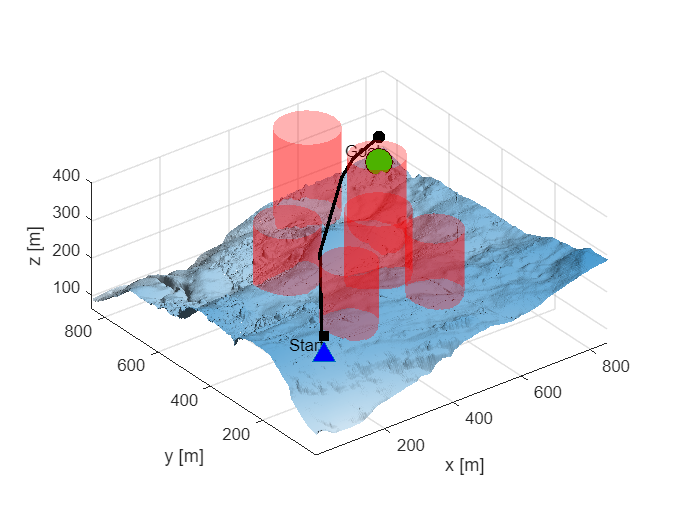

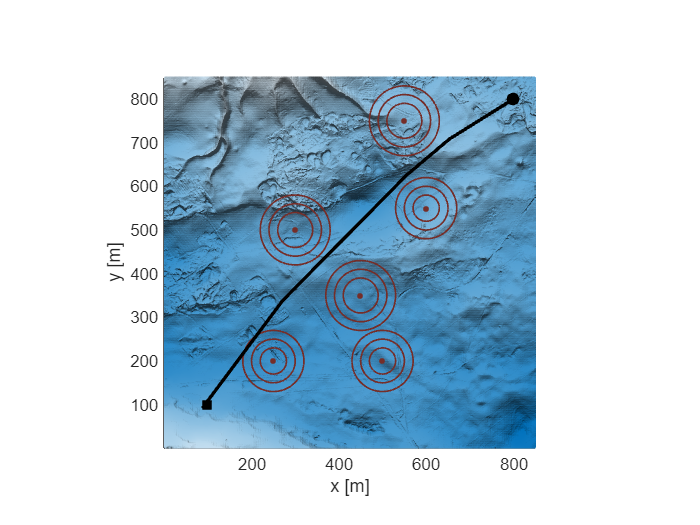

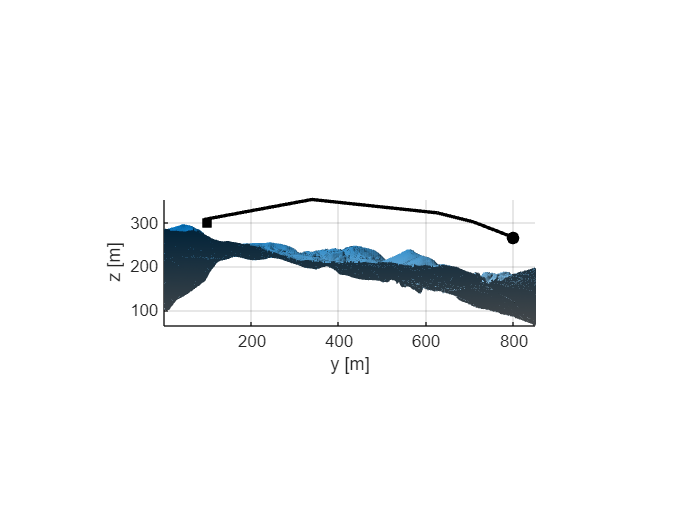

smooth = 0.95;
PlotSolution(BestPosition,model,smooth);

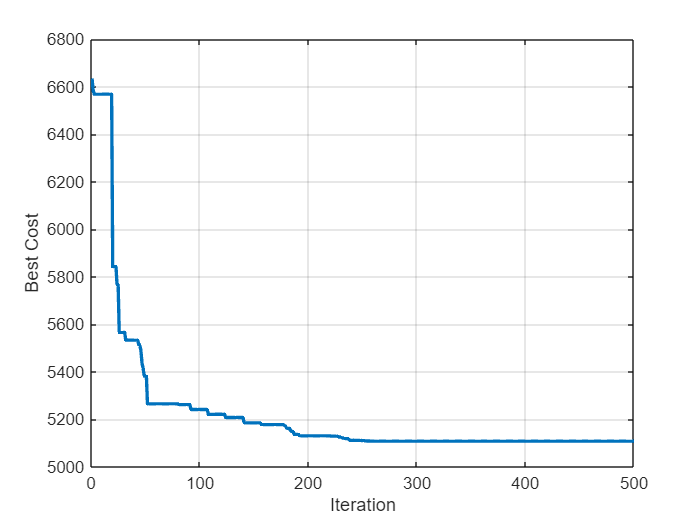


% Best cost  
figure;
plot(BestCost,'LineWidth',2);
xlabel('Iteration');
ylabel('Best Cost');
grid on;

BestCost(end)

ans =           5108.53615228032
